# Non Cartesian Coordinates (1D)

clear, close all, clc
set_defaults()

The advantage of the dyadic notation ($\nabla$, $\nabla \cdot$,$\nabla \times$) is that it hides the coordinate system. Here we show that the same can be achived by the discrete operators. Currently we have only discretized one coordinate direction, but this already allows three different coordinate systems

- linear (1D)

- cylindrical radial (2D)

- spherical radial (3D)

The *gradient* is identical in all three coordinate systems: $\nabla = \frac{\mathrm{d}}{\mathrm{d}x}$

Here we also use the independet variable $x$ to denote the radial direction in 2D and 3D.

In contrast to the gradient the *divergence* changes with the coordinate system

- linear (1D): $\nabla\cdot = \frac{\mathrm{d}}{\mathrm{d}x}$

- cylindrical radial (2D): $\nabla\cdot =\frac{1}{x} \frac{\mathrm{d}}{\mathrm{d}x}x $

- spherical radial (3D): $\nabla\cdot =\frac{1}{x^2} \frac{\mathrm{d}}{\mathrm{d}x}x^2$

Therefore we can write the general radial divergence in $d$ dimensions as: $\nabla\cdot =\frac{1}{x^{(d-1)}} \frac{\mathrm{d}}{\mathrm{d}x}x^{(d-1)}$

## Geometric interpretation of the radius terms

The key to the correct discretization is the geometric understanding of the two radius terms in the divergence. To facilitate this consider the equation for the steady state temperature with a heat source

in compact dyadic notation$-\nabla\cdot\left[\kappa \nabla T\right] = f_s$  

or written explicitly in terms of the radial coordinate  $-\frac{\mathrm{d}}{\mathrm{d}x}\left[x^{(d-1)}\kappa \frac{\mathrm{d}T}{\mathrm{d}x}\right] = x^{(d-1)}f_s$.

Note, here we have multiplied through by $x^{(d-1)}$, so that it is on the right hand side. In this form, the geometric origin of the two radius terms becomes clearer.

- The term $x^{(d-1)}\kappa$ suggests that this $x^{(d-1)}$ represents that growth of the interfacial area with increasing radius, because $\kappa
$ is associate with the flux. This radius term should therefore evaluated at the cell faces `Grid.xf`.

- The term $x^{(d-1)}f_s$ suggests that this $x^{(d-1)}$ represents the growth of the volume with increasing radius, because $f_s$ is the volumetic source term. This radius term should therefore be evaluated at the cell centers `Grid.xc`.

## Discretization of the divergence

The radial component of the discrete divergence matrix in cylindical and spherical geometry can therefore be obtained as follows:

kappa = 1;
Grid.xmin = 0.1; Grid.xmax = 1; Grid.Nx = 35;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
fs = spalloc(Grid.Nx,1,0);

% General radial coordinate system
Rinv = @(d) spdiags(1./Grid.xc.^(d-1),0,Grid.Nx,Grid.Nx);
R = @(d) spdiags(Grid.xf.^(d-1),0,Grid.Nfx,Grid.Nfx);
D = @(d) Rinv(d)*D*R(d);
L = @(d) -D(d)*kappa*G;

Note that including the origin, $r=0$, is not a problem because the term $1/x^{1-d}$ is evaluated at cell centers!

## Test problem 1: Steady state conduction across cylindrical and spherical shells

This simple problem nicely illustrates the effect of geometry on the steady tempretaure profile.

$-\frac{1}{x^{(d-1)}}\frac{\mathrm{d}}{\mathrm{d}x}\left[x^{(d-1)}\kappa \frac{\mathrm{d}T}{\mathrm{d}x}\right] = 0$  for  $x \in \left[x_{min},\,x_{max}\right]$

with the Dirichlet BC's $T(x_{min}) = T_1$ and $T(x_{max}) = T_2$, where $x_{min} > 0$.

The analytic solutions are given by

- linear (1D): $T(x) = T_1 + \frac{T_2-T_1}{r_{max}-r_{min}}(r-r_{min})$

- clylindrical (2D): $T(x) = T_1 + (T_2-T_1)\frac{\ln(r/r_{min})}{\ln(r_{max}/r_{min})}$

- spherical (3D): $T(x) = T_1 + \frac{T_2-T_1}{\frac{1}{r_{max}}-\frac{1}{r_{min}}}\left(\frac{1}{r}-\frac{1}{r_{min}}\right)$

T1 = 1;
T2 = 0;
xana = linspace(Grid.xmin,Grid.xmax,1e2);
u1d_ana = @(x) T1 + (T2-T1)/(Grid.Lx)*(x-Grid.xmin);
u2d_ana = @(x) T1 + (T2-T1)*log(x/Grid.xmin)/log(Grid.xmax/Grid.xmin);
u3d_ana = @(x) T1 + (T2-T1)/(1/Grid.xmax-1/Grid.xmin)*(1./x-1/Grid.xmin);


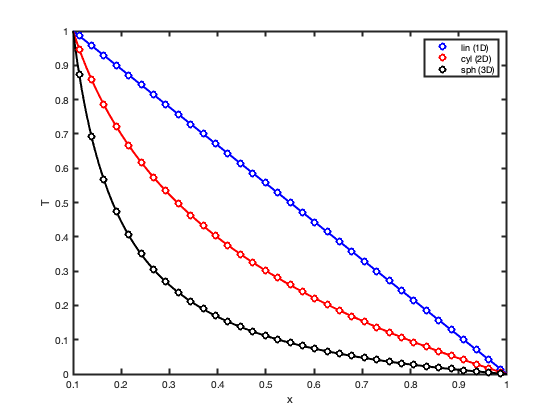


Param.dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
Param.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
Param.dof_neu = [];
Param.dof_f_neu = [];

% 1D - linear
Param.g = u1d_ana(Grid.xc(Param.dof_dir));
[B,N,fn] = build_bnd(Param,Grid,I);
u1d = solve_lbvp(L(1),fs+fn,B,Param.g,N);
plot(Grid.xc,u1d,'bo','markerfacecolor','w','markersize',6), hold on

% 2D - cylindrical
Param.g = u2d_ana(Grid.xc(Param.dof_dir));
% [B,N,fn] = build_bnd(Param,Grid,I);
u2d = solve_lbvp(L(2),fs+fn,B,Param.g,N);
plot(Grid.xc,u2d,'ro','markerfacecolor','w','markersize',6)

% 3D - spherical
Param.g = u3d_ana(Grid.xc(Param.dof_dir));
% [B,N,fn] = build_bnd(Param,Grid,I);
u3d = solve_lbvp(L(3),fs+fn,B,Param.g,N);
plot(Grid.xc,u3d,'ko','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'T'

plot(xana,u1d_ana(xana),'b-')
plot(xana,u2d_ana(xana),'r-')
plot(xana,u3d_ana(xana),'k-')
plot(Grid.xc,u1d,'bo','markerfacecolor','w','markerfacecolor','w','markersize',6)
plot(Grid.xc,u2d,'ro','markerfacecolor','w','markerfacecolor','w','markersize',6)
plot(Grid.xc,u3d,'ko','markerfacecolor','w','markerfacecolor','w','markersize',6), hold off
legend('lin (1D)','cyl (2D)','sph (3D)')

If we set the boundary conditions using the analytical solution at the cell centers, the numerical solution matches the anaytic solution very well. Our discrete divergence in cylindrical and spherical radial coordinates is therefore correct.

Note how the Temperature decays more rapidly with distance in higher coordinates. This is because the heat flow is distributed into shells of in creasing volume in 2D and 3D. 

## Example: Temperatures in the Moon

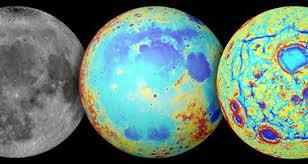

With the recent [NASA GRAIL](https://www.nasa.gov/mission_pages/grail/main/index.html) mission (Image above) the our understanding of the Moon has been revolutionized. 

The Moon is a realtively small planetary body (radius 1738 Km), so it is a relatively good assumption to assume its density is constant with depth. The Moon also does not have plate tectonics and associated convective heat transport in the interior. Therefore the steady conductive heat equation is likely to give a good first-order approximation to the internal temperature of the moon. Becuase the moon is likey to have formed from the Earth during a giant impact between the proto-Earth and an Mars sized impactor we can assume that its bulk properties are similar to the Earth. Hence, we assume the following paramters:

H = 7.38e-12; % mean heat production [W/kg]
rho = 3300;   % mean density [kg/m^3]
R = 1738e3;   % Radius of the moon [m]
T0 = 250;     % mean surface temperature [K]
kappa = 3.3;  % mean thermal conductivity [W/(m K)]

To compute the steady temerature profile in an asteroid of radius, $R$, heated uniformly by radioactive decay we solve

$-\frac{1}{r^2}\frac{\mathrm{d}}{\mathrm{d}r}\left[r^2\kappa \frac{\mathrm{d}T}{\mathrm{d}r}\right] = \rho H$  for  $r \in \left[0,\,R\right]$

with the Dirichlet BC $T(R) = T_{0}$ and the natural (no heat flow) BC at the center. The analytic solutions for temperature and heat flux are given by

$T = T__0 + \frac{\rho H }{6 k}\left(R^2-r^2\right)$ and $q = \rho H r/3$.

Tmoon = @(r) T0 + rho*H/6/kappa*(R^2-r.^2);
qmoon = @(r) rho*H*r/3;
rplot = linspace(0,R,1e2);

## Numerical solution

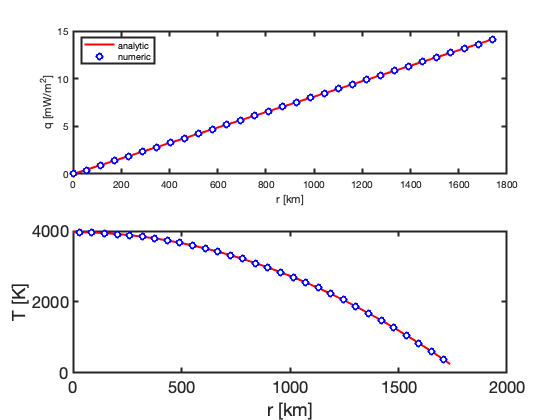

Grid.xmin = 0; Grid.xmax = R; Grid.Nx = 30;
Grid.geom = 'spherical_r';
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*kappa*G; fs = rho*H*ones(Grid.Nx,1);

BC.dof_dir   = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = Tmoon(R-Grid.dx/2); % use analytic solution to set BC in center of cell
BC.dof_neu = []; BC.dof_f_neu = []; BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);

u = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,kappa,G,u,fs,Grid,BC);

clf
subplot 211
plot(rplot/1e3,qmoon(rplot)*1e3,'r-'), hold on
plot(Grid.xf/1e3,q*1e3,'bo','markerfacecolor','w','markersize',6), hold off
xlabel 'r [km]', ylabel 'q [mW/m^2]'
legend('analytic','numeric','location','northwest')

subplot 212
plot(rplot/1e3,Tmoon(rplot),'r-'), hold on
plot(Grid.xc/1e3,u,'bo','markerfacecolor','w','markersize',6)
xlabel 'r [km]', ylabel 'T [K]'

# Auxillary functions

## set_defaults()

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end